function list = fib(n)
    list = [1,1];
    while true
        next = list(end-1) + list(end);
        if next<n
            list(end+1) = next;
        else
            break;
        end
    end
end

fib(119)

ans =      1     1     2     3     5     8    13    21    34    55    89


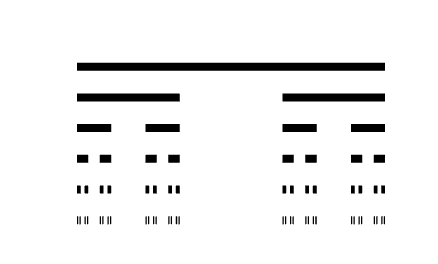

function plot_cantor(N)
if nargin<1, N=6; end
intervals = [0 1];
figure; hold on; axis off
ylim([-0.5 N+0.5]); xlim([-0.05 1.05])

for k=0:N-1
    y = N - k;
    for i=1:size(intervals,1)
        a = intervals(i,1); b = intervals(i,2);
        plot([a b],[y y],'k','LineWidth',6)
    end
    new = [];
    for i=1:size(intervals,1)
        a = intervals(i,1); b = intervals(i,2);
        L = a + (b-a)/3; R = b - (b-a)/3;
        new = [new; a L; R b];
    end
    intervals = new;
end

for i=1:size(intervals,1)
    a = intervals(i,1); b = intervals(i,2);
    plot([a b],[0 0],'k','LineWidth',2)
end
end

plot_cantor(6)